# **TASK 3**

# **3.1.a)**

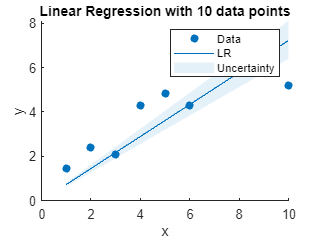

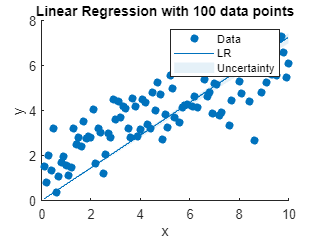

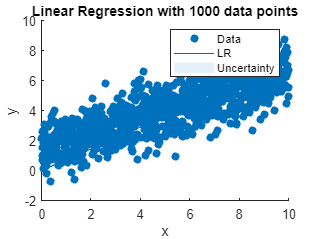

clear;
% Constants
noise_variance = 1;
sample_sizes = [10, 100, 1000];

% Store estimates and MSE for each sample size
theta_estimates = zeros(length(sample_sizes), 2); % Assuming a model with 2 parameters
mse_values = zeros(length(sample_sizes), 1);

% Loop over each sample size
for i = 1:length(sample_sizes)
    N = sample_sizes(i);
    
    % Generate dataset
    [X, y] = linearData(N, noise_variance, 0);
    
    % linear regression model
    m = LinRegress(X, y);
    theta_estimates(i, :) = m.theta';
    
    % MSE
    y_pred = evalModel(m, X);
    mse_values(i) = mean((y - y_pred).^2);
    
    % model against the data
    figure;
    plotModel(X, y, m);
    title(sprintf('Linear Regression with %d data points', N));
end


% results
disp('Theta Estimates:');

Theta Estimates:


disp(theta_estimates);

    0.7216    0.7216
    0.7266    0.7266
    0.7240    0.7240



disp('MSE Values:');

MSE Values:


disp(mse_values);

    1.0628
    1.6083
    1.6184



# **3.1.b)**

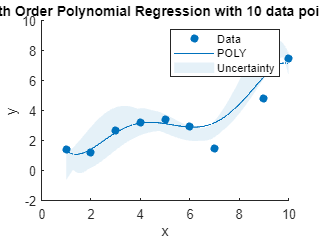

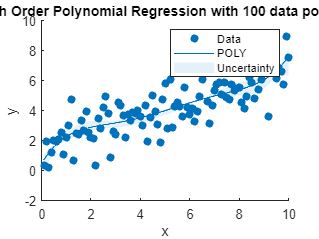

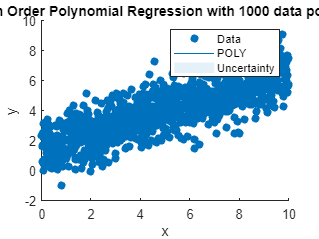

clear;
noise_variance = 1;
sample_sizes = [10, 100, 1000];
degree = 5; % polynom degree

for i = 1:length(sample_sizes)
    N = sample_sizes(i);
    
    % dataset
    [X, y] = linearData(N, noise_variance, 0);
    
    % init X_poly with a column of ones for the intercept term
    X_poly = ones(N, 1);

    % design matrix for a 5th order polynomial
    for d = 1:degree
        X_poly = [X_poly, X.^d];
    end
    
    m_poly = polyfit(X, y, 0, degree); % 0 for lambda since we're not regularizing
    
    % predictions
    y_pred_poly = evalModel(m_poly, X_poly);
    
    % MSE 
    mse_values_poly(i) = mean((y - y_pred_poly).^2);
    
    % model against the data
    figure;
    plotModel(X, y, m_poly);
    title(sprintf('5th Order Polynomial Regression with %d data points', N));
end


% MSE values
disp('MSE Values for 5th Order Polynomial Regression:');

MSE Values for 5th Order Polynomial Regression:


disp(mse_values_poly);

    1.2040    1.0255    1.0839



# **3.1.c)**

clear;
N = 100; % data points in each dataset
num_simulations = 100; % Monte Carlo simulations
noise_variance = 1; % Variance of the noise
true_parameters = [2; -3]; % True parameters (intercept and slope)

theta_estimates = zeros(num_simulations, 2); % Initialize storage for parameter estimates

% Monte Carlo Simulation for parameter estimation
for i = 1:num_simulations
    % Generate dataset with noise
    X = [ones(N, 1), (1:N)']; % Design matrix with intercept and linear term
    e = randn(N, 1) * sqrt(noise_variance); % Generate random noise
    y = X * true_parameters + e; % Generate responses with noise
    
    % Estimate parameters using custom linear regression function
    m = LinRegress(X, y); 
    
    % Store the estimated parameters
    theta_estimates(i, :) = m.theta';
end

% Plot histograms of the estimated parameters
figure;
histogram(theta_estimates(:,1), 'BinMethod', 'auto'); % Histogram for intercept estimates
hold on;
histogram(theta_estimates(:,2), 'BinMethod', 'auto'); % Histogram for slope estimates
hold off;

% Calculate and display empirical variances of the parameter estimates
empirical_variance_intercept = var(theta_estimates(:,1));
empirical_variance_slope = var(theta_estimates(:,2));
disp(['Empirical Variance of Intercept Estimates: ', num2str(empirical_variance_intercept)]);
disp(['Empirical Variance of Slope Estimates: ', num2str(empirical_variance_slope)]);

# **3.1.d)**

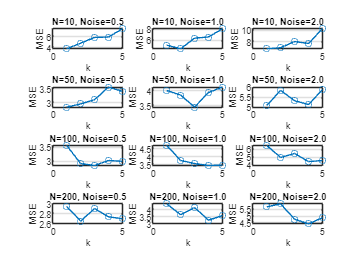

clear;
sample_sizes = [10, 50, 100, 200]; % to test
noise_variances = [0.5, 1, 2]; % noise levels to test
k_values = 1:5; % k values to try
num_simulations = 50; % no. of simulations for each setting

% Inits.
results = struct();
figure;
% Total number of plots
total_plots = length(sample_sizes) * length(noise_variances);
plot_number = 1; % Init plot counter

% Loop over sample sizes and noise variances
for N = sample_sizes
    for noise_variance = noise_variances
        
        % space for MSE values for each k
        mse_for_k = zeros(length(k_values), 1);
        
        for k = k_values
            mse_total = 0; 

            % Monte Carlo Simulations for the current setting
            for sim = 1:num_simulations
                % Generating data
                [X, y] = linearData(N, noise_variance, 0);

                % Splitting into train and validation sets
                % using a simple 50-50 split for plotting purposes
                half = floor(N / 2);
                X_train = X(1:half, :);
                y_train = y(1:half, :);
                X_val = X(half+1:end, :);
                y_val = y(half+1:end, :);

                % Trainin KNN model
                m_knn = knnRegress(X_train, y_train, k);

                % Validating KNN model
                y_pred = evalModel(m_knn, X_val);
                mse = mean((y_val - y_pred).^2);
                mse_total = mse_total + mse;
            end
            
            % average MSE for k
            mse_for_k(k) = mse_total / num_simulations;
        end
        
        % results
        results(N).(strcat('noise_', strrep(num2str(noise_variance), '.', 'p'))) = mse_for_k;

        subplot(length(sample_sizes), length(noise_variances), plot_number);
        plot(k_values, mse_for_k, '-o');
        title(sprintf('N=%d, Noise=%0.1f', N, noise_variance));
        xlabel('k');
        ylabel('MSE');
        grid on; 
        plot_number = plot_number + 1;
        
    end
end

# **3.2.a)**

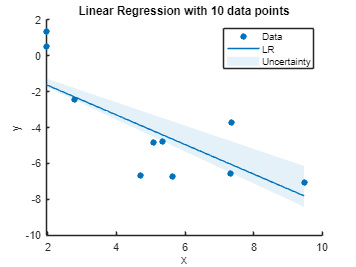

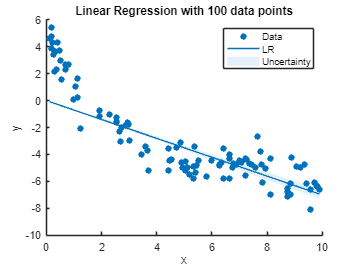

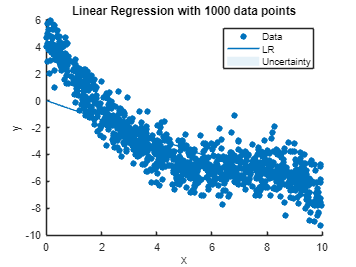

noise_variance = 1;
sample_sizes = [10, 100, 1000];

% estimates and MSE for each sample size
theta_estimates = zeros(length(sample_sizes), 2); % Assuming a model with 2 parameters
mse_values = zeros(length(sample_sizes), 1);

for i = 1:length(sample_sizes)
    N = sample_sizes(i);
    
    % Generate dataset
    [X, y] = polyData(N, noise_variance, 0);
    
    % Estimatin linear regression model
    m = LinRegress(X, y);
    
    % Store estimates
    theta_estimates(i, :) = m.theta';
    
    % MSE
    y_pred = evalModel(m, X);
    mse_values(i) = mean((y - y_pred).^2);
    
    figure;
    plotModel(X, y, m);
    title(sprintf('Linear Regression with %d data points', N));
end


% results
disp('Theta Estimates:');

Theta Estimates:


disp(theta_estimates);

   -0.8254   -0.8254
   -0.7026   -0.7026
   -0.7103   -0.7103



disp('MSE Values:');

MSE Values:


disp(mse_values);

    3.2388
    3.3424
    3.0729



# **3.2.b)**

clear;
noise_variance = 1;
N = 15; % Small dataset 
degrees = 1:10; % Polynomial degrees to try
regularization_params = [0.01, 0.1, 1, 10, 100]; % regularization strengths to compare

mse_values_poly_reg = zeros(length(degrees), length(regularization_params));
[X, y] = polyData(N, noise_variance, 0);

for i = 1:length(degrees)
    degree = degrees(i);
    
    % regularization params
    for j = 1:length(regularization_params)
        lambda = regularization_params(j);
        
        % Extending X to include polynomial terms up to degree
        X_poly = [ones(N, 1)]; % column for intercept
        for d = 1:degree
            X_poly = [X_poly, X.^d];
        end
        
        m_poly_reg = LinRegressRegul(X_poly, y, lambda);
        y_pred_poly_reg = evalModel(m_poly_reg, X_poly);
        mse_values_poly_reg(i, j) = mean((y - y_pred_poly_reg).^2);
    end
end

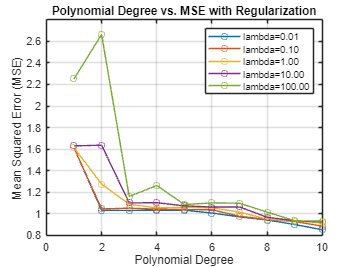


figure;
for j = 1:length(regularization_params)
    plot(degrees, mse_values_poly_reg(:, j), '-o', 'DisplayName', sprintf('lambda=%.2f', regularization_params(j)));
    hold on;
end
title('Polynomial Degree vs. MSE with Regularization');
xlabel('Polynomial Degree');
ylabel('Mean Squared Error (MSE)');
legend('show');
grid on;
hold off;

# **3.2.c)**

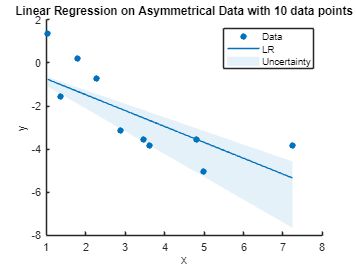

%with asymetrical data -> increased error or biased
clear;
noise_variance = 1;
N = 10; 

% asymmetrical dataset using polyData with a third argument set to '1'
[X, y] = polyData(N, noise_variance, 1);
m_linear = LinRegress(X, y);
y_pred_linear = evalModel(m_linear, X);
mse_linear = mean((y - y_pred_linear).^2);

% model against the data
figure;
plotModel(X, y, m_linear);
title(sprintf('Linear Regression on Asymmetrical Data with %d data points', N));


% results
disp('Theta Estimates for Asymmetrical Data:');

Theta Estimates for Asymmetrical Data:


disp(m_linear.theta');

   -0.7384



disp('MSE for Asymmetrical Data:');

MSE for Asymmetrical Data:


disp(mse_linear);

    1.5618



# **3.2.d)**

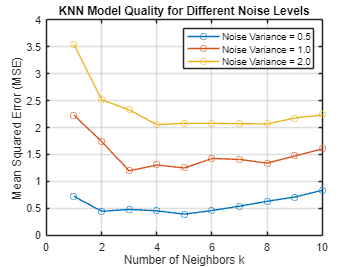

clear;
%Model Quality for Different Noise Levels. 
sample_size = 100; % fixed sample size for this one
noise_variances = [0.5, 1, 2]; 
k_values = 1:10; % k values to test

% Preallocate space for storing MSE values
mse_for_k = zeros(length(k_values), length(noise_variances));

% noise variances lopp
for j = 1:length(noise_variances)
    noise_variance = noise_variances(j);

    % Generate dataset
    [X, y] = polyData(sample_size, noise_variance, 0);

    % Splitting into training and testing datasets
    % using a 70-30 split for plotting purposes
    idx = randperm(sample_size);
    train_idx = idx(1:round(0.7 * sample_size));
    test_idx = idx(round(0.7 * sample_size) + 1:end);
    X_train = X(train_idx, :);
    y_train = y(train_idx);
    X_test = X(test_idx, :);
    y_test = y(test_idx);

    % k values
    for i = 1:length(k_values)
        k = k_values(i);

        % Training KNN model
        m_knn = knnRegress(X_train, y_train, k);

        % Validating KNN model
        y_pred = evalModel(m_knn, X_test);
        mse_for_k(i, j) = mean((y_test - y_pred).^2);
    end
end

% MSE vs k for each noise level
figure;
for j = 1:length(noise_variances)
    plot(k_values, mse_for_k(:, j), '-o', 'DisplayName', sprintf('Noise Variance = %.1f', noise_variances(j)));
    hold on;
end
xlabel('Number of Neighbors k');
ylabel('Mean Squared Error (MSE)');
title('KNN Model Quality for Different Noise Levels');
legend('show');
grid on;

# **3.3.a)**

clear;
%how the complexity of polynomial regression models 
% (varied through polynomial degrees) interacts with 
% different dataset sizes to affect model performance
noise_variance = 0.2;
small_N = 50;
large_N = 1000;
degrees = 1:10; % polynom degrees to try

[X_small, y_small] = chirpData(small_N, noise_variance); % small dataset

% Fit models and calculate MSE for the small dataset
mse_small = zeros(length(degrees), 1);
for i = 1:length(degrees)
    % polynomial features
    X_poly = poly_x2(X_small, degrees(i));
    % Fit polynomial regress
    model = polyfit(X_small, y_small, 0, degrees(i)); 
    % predictions and MSE
    y_pred = evalModel(model, X_poly); 
    mse_small(i) = mean((y_small - y_pred).^2);
end

% smallest MSE for the small dataset + best degree
[~, best_degree_small] = min(mse_small);

% for the large dataset
[X_large, y_large] = chirpData(large_N, noise_variance);
mse_large = zeros(length(degrees), 1);
for i = 1:length(degrees)
    X_poly = poly_x2(X_large, degrees(i));
    model = polyfit(X_large, y_large, 0, degrees(i)); 
    y_pred = evalModel(model, X_poly); 
    mse_large(i) = mean((y_large - y_pred).^2);
end

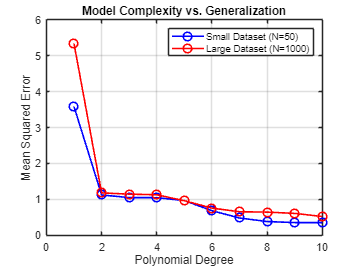


% smallest MSE for the large dataset + best degree
[~, best_degree_large] = min(mse_large);
% Plot MSE against polynomial degree
figure;
plot(degrees, mse_small, 'b-o', 'LineWidth', 1.5, 'MarkerSize', 8);
hold on;
plot(degrees, mse_large, 'r-o', 'LineWidth', 1.5, 'MarkerSize', 8);
hold off;
xlabel('Polynomial Degree');
ylabel('Mean Squared Error');
title('Model Complexity vs. Generalization');
legend(['Small Dataset (N=', num2str(small_N), ')'], ['Large Dataset (N=', num2str(large_N), ')']);
grid on;

fprintf('Best degree for small dataset (%d data points): %d with an MSE of %.4f\n', small_N, best_degree_small, mse_small(best_degree_small));

Best degree for small dataset (50 data points): 10 with an MSE of 0.3462


fprintf('Best degree for large dataset (%d data points): %d with an MSE of %.4f\n', large_N, best_degree_large, mse_large(best_degree_large));

Best degree for large dataset (1000 data points): 10 with an MSE of 0.5167


# **3.3.b)**

clear;
noise_variance = 0.1;
N = 50; % data points
degree = 10; % High-degree polynomial to try
regularization_params = [0.01, 0.1, 1, 10, 100]; % Regularization strengths

% dataset
[X, y] = chirpData(N, noise_variance);

% arrays for storing results
mse_values = zeros(length(regularization_params), 1);
models = cell(length(regularization_params), 1);

% regularization parameters to fit models and find MSE
for i = 1:length(regularization_params)
    lambda = regularization_params(i);
    
    % polynomial features up to the spec. degree
    [X_poly, ~] = poly_x2(X, degree);
    
    % Fit polynomial regress with regularization
    models{i} = polyfit(X, y, lambda, degree);
    
    % predictions using the polynomial features and MSE
    y_pred = evalModel(models{i}, X_poly);
    mse_values(i) = mean((y - y_pred).^2);
end


% regularization parameter with the smallest MSE
[best_mse, best_idx] = min(mse_values);
best_lambda = regularization_params(best_idx);
best_model = models{best_idx};
fprintf('The best regularization parameter is %f with an MSE of %.4f\n', best_lambda, best_mse);

The best regularization parameter is 0.010000 with an MSE of 0.1010


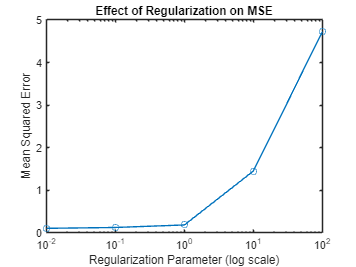

figure;
semilogx(regularization_params, mse_values, '-o');
title('Effect of Regularization on MSE');
xlabel('Regularization Parameter (log scale)');
ylabel('Mean Squared Error');

# **3.3.c)**

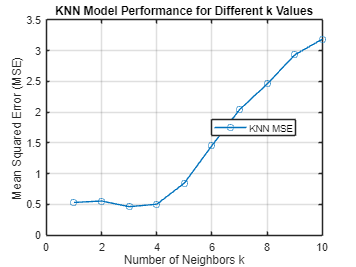

clear;
noise_variance = 0.2; 
N = 50; 
k_values = 1:10; 
[X, y] = chirpData(N, noise_variance);

% training and validation sets
idx = randperm(N);
train_idx = idx(1:floor(0.7 * N)); % 70% for training
val_idx = idx(floor(0.7 * N) + 1:end); % 30% for validation
X_train = X(train_idx);
y_train = y(train_idx);
X_val = X(val_idx);
y_val = y(val_idx);

mse_values_knn = zeros(length(k_values), 1);
% KNN models for different k values
for i = 1:length(k_values)
    k = k_values(i);
    
    % Training
    m_knn = knnRegress(X_train, y_train, k);
    
    % Validating
    y_pred_knn = evalModel(m_knn, X_val);
    mse_values_knn(i) = mean((y_val - y_pred_knn).^2);
end

% MSE vs. k
figure;
plot(k_values, mse_values_knn, '-o');
xlabel('Number of Neighbors k');
ylabel('Mean Squared Error (MSE)');
title('KNN Model Performance for Different k Values');
legend('KNN MSE', 'Location', 'best');
grid on;


% best k based on the lowest MSE
[best_mse, best_k_idx] = min(mse_values_knn);
best_k = k_values(best_k_idx);
fprintf('Best k by MSE: %d with an MSE of %.2f\n', best_k, best_mse);

Best k by MSE: 3 with an MSE of 0.46


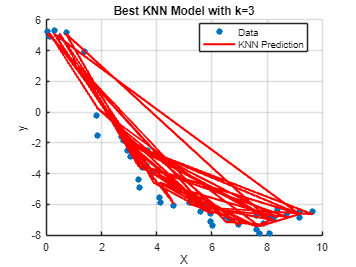


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% best KNN model against the data
best_knn_model = knnRegress(X_train, y_train, best_k);
y_pred_best_knn = evalModel(best_knn_model, X);
figure;
scatter(X, y, 'filled');
hold on;
plot(X, y_pred_best_knn, 'r-', 'LineWidth', 2);
xlabel('X');
ylabel('y');
title(sprintf('Best KNN Model with k=%d', best_k));
legend('Data', 'KNN Prediction', 'Location', 'best');
grid on;

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

# **Functions Developed:**

function m = LinRegress(x,y)
    [Ny,ny] = size(y);
    [Nx,nx] = size(x);
    m.model = 'LR'; % linear regr.model
    
    if Nx == Ny % Test that the number of data is the same in x and y
        
        m.theta = (x'*x)\(x'*y);
           
        if ny == 1 % calculate uncertainty only in the case that there is one output
            
            % Estimating the variance of the error term
            residuals = y - x * m.theta; %error terms for each observation, indicating how much the model's 
                                         % prediction deviates from the actual observed value

            sigma2 = (residuals' * residuals) / (Ny - nx); % according to 4.13 the residuals should be
                                                           % times 2, however this leads to high deviations 
                                                           % between the estimated and true covariance 
            % variance of the parameters
            m.variance = sigma2 * inv(x' * x); % covariance of theta_hat
            
        else
           m.variance = 'None';
        end
    else
        m.theta = NaN;
        m.model = 'None';
        m.variance = 'None';
        disp('Dimension mismatch for output and regressor.')
    end
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function y_pred = evalModel(m, X)
    if strcmp(m.model, 'LR') || strcmp(m.model, 'POLY') % Linear or Polynomial models

        y_pred = X * m.theta(:);

    elseif strcmp(m.model, 'knn') % KNN model
        y_pred = zeros(size(X, 1), 1); % Initializing the output

        for i = 1:size(X, 1)
            % For each input point we find the k nearest neighbor
            distances = sqrt(sum(bsxfun(@minus, m.x, X(i)).^2, 2));
            [~, sortedIndices] = sort(distances);
            closestIndices = sortedIndices(1:m.k);
            y_pred(i) = mean(m.y(closestIndices));
        end

    else
        error('Unknown model type');
    end
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function m = LinRegressRegul(x, y, lambda)
    % Appending extra rows to x and y for regularization
    x2 = [x; sqrt(lambda)*eye(size(x,2))];
    y2 = [y; zeros(size(x,2), 1)];
    
    % LinRegress function on the updated x2 and y2
    m = LinRegress(x2, y2);
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function [x2, allpot] = poly_x2(x, n)
    [Nx, nx] = size(x);

    % Generate all possible combinations of exponents for the monomials
    if nx == 1
        % If only one regressor, simply generate the powers of it
        allpot = (0:n)';
    else
        % Generate combinations for multiple regressors
        allpot = [];
        for total_degree = 0:n
            % Generate and append combinations for the current total degree
            allpot = [allpot; flipud(generateCombinations(nx, total_degree))];
        end
    end
    
    % Number of monomials is the number of rows in allpot
    nmon = size(allpot, 1);
    
    % Prepare an empty matrix for the extended regressor matrix
    x2 = ones(Nx, nmon);
    
    % Fill in the x2 matrix
    for ii = 1:nmon
        % Calculate each monomial using one row of allpot and x
        for var_idx = 1:nx
            x2(:, ii) = x2(:, ii) .* (x(:, var_idx) .^ allpot(ii, var_idx));
        end
    end
end

function combinations = generateCombinations(num_vars, total_degree)
    % Generate all combinations of exponents for num_vars summing to total_degree
    if num_vars == 1
        combinations = total_degree;
    else
        combinations = [];
        for i = 0:total_degree
            % Recursively generate combinations for one less variable
            sub_combinations = generateCombinations(num_vars - 1, total_degree - i);
            % Prepend the current exponent to each combination
            combinations = [combinations; [i * ones(size(sub_combinations, 1), 1), sub_combinations]];
        end
    end
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function m = polyfit(x, y, lambda, n)
    % Generating the extended regressor matrix
    [x2, allpot] = poly_x2(x, n);

    % regularized linear regression using the extended matrix
    m = LinRegressRegul(x2, y, lambda);

    % Adding the degree of the polynomial and model type to the structure
    m.n = n;
    m.model = 'POLY'; % polynomial regr.model
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function plotModel(x, y, varargin)

    scatter(x, y, 'filled', 'DisplayName', 'Data'); % for data points
    hold on;
    
    % Colors for plotting each model
    colors = lines(max(length(varargin), 1));

    % plotting the models smoothly
    x2 = linspace(min(x), max(x), 1000)';  % A vector for predictions
                                           % could have been x2=(-5:0.1:5)';  
                                           % according to Test_plotModel

    for i = 1:length(varargin)
        m = varargin{i};

        % Check-point for the model type
        if strcmp(m.model, 'knn')
            % KNN model
            y_pred = evalModel(m, x2); % Directly use x2 for KNN
            plot(x2, y_pred, 'Color', colors(i,:), 'DisplayName', 'KNN');
        elseif strcmp(m.model, 'POLY')
            % Polynomial model
            X_design = poly_x2(x2, m.n);
            y_pred = evalModel(m, X_design);
            plot(x2, y_pred, 'Color', colors(i,:), 'DisplayName', 'POLY');
        else
            % Linear model
            X_design = [ones(size(x2, 1), 1), x2];
            y_pred = evalModel(m, X_design);
            % excluding the intercept term (1st column) for plotting purposes
            [yr, yc] = size(y_pred);
            if yc >= 2
                y_pred = y_pred(:,2:end);
                plot(x2, y_pred, 'Color', colors(i,:), 'DisplayName', 'LR');
            else
                plot(x2, y_pred, 'Color', colors(i,:), 'DisplayName', 'LR');
            end

        end


        % Plot uncertainty for a single model with variance information
        if length(varargin) == 1 && isfield(varargin{1}, 'variance') && ...
                size(varargin{1}.variance, 1) == size(varargin{1}.variance, 2)
   
            m = varargin{1};
    
            % Generating the design matrix depending on the model type
            if strcmp(m.model, 'LR')
                X_design = [ones(size(x2, 1), 1), x2];  % Adding intercept for linear regression
            elseif strcmp(m.model, 'POLY')
                X_design = poly_x2(x2, m.n);  % Already includes the intercept in the design
            end
%%%% %%%% %%%% %%%% %%%% %%%% %%%% %%%% %%%% %%%% %%%% %%%% %%%% %%%% %%%% %%%% %%%% %%%% %%%% %%%%  
            num_samples = 5;  %%%%%%% ADJUST %%%%%%%
%%%% %%%% %%%% %%%% %%%% %%%% %%%% %%%% %%%% %%%% %%%% %%%% %%%% %%%% %%%% %%%% %%%% %%%% %%%% %%%%  

            y_sims = zeros(length(x2), num_samples);

            % Generatin outputs for each sample using Monte Carlo simu.
            for i = 1:num_samples
                % Sample from the parameter distribution
                theta_sample = mvnrnd(m.theta, m.variance);
        
                % checkin the model with the sampled paras
                if strcmp(m.model, 'POLY')
                    y_sims(:, i) = evalModel(struct('theta', theta_sample, 'model', m.model), X_design);
                else
                    % x2 can be passed directly
                    y_sims(:, i) = evalModel(struct('theta', theta_sample, 'model', m.model), x2);
                end
            end

            % the 2.5th and 97.5th percentiles
            y_lower = prctile(y_sims, 2.5, 2);
            y_upper = prctile(y_sims, 97.5, 2);
    
            % Plotting the uncertainty region
            fill([x2; flipud(x2)], [y_upper; flipud(y_lower)], ...
                colors(1,:), 'FaceAlpha', 0.1, 'EdgeColor', 'none', 'DisplayName', 'Uncertainty');
        end

        
    end

    xlabel('x');
    ylabel('y');
    legend show;
    hold off;
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function m = knnRegress(x, y, k)
    % KNN model
    m.x = x;
    m.y = y;
    m.k = k;
    m.model = 'knn'; 
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%